# Examen Final 6 (Robot Planar 2 GDL)

Para este Examen final se nos pidió que realizaremos el análisis y los cálculos pertinentes para calcular modelo del torque de cada articulación, la matriz de inercia, el modelo de las fuerzas centrípetas y de Coriolis y el modelo del par gravitacional de un robot planar de 2 gdl por medio de un live script de MatLab:

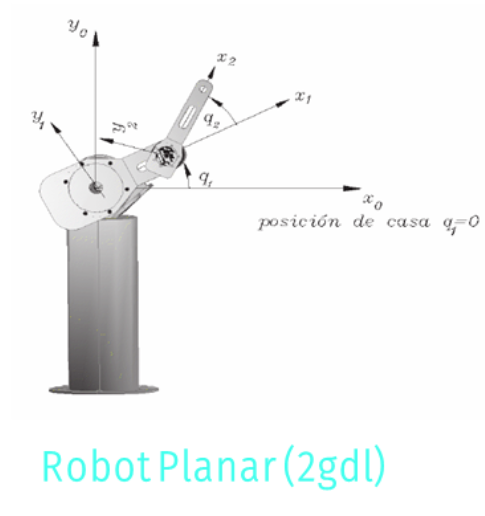

Empezamos con la limpieza de nuestra terminal e inicializamos un temporizador que nos dará el tiempo transcurrido en la ejecución del programa:

%Limpieza de pantalla
clear all
close all
clc

%Temporizador
tic

Continuamos con la declaración de la variables simbólicas que utilizaremos mas adelante:

%Declaración de variables simbólicas

%Angulos de cada articulación
syms th1(t) th2(t) t  
%Velocidades de cada articulación
syms th1p(t) th2p(t)  
%Aceleraciones de cada articulación
syms th1pp(t) th2pp(t) 
%Masas y matrices de Inercia
syms m1 m2  Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 
%l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms l1 l2 lc1 lc2  
syms pi g a cero

Creamos el vector de coordenadas (posición) para las articulaciones, una ves que contamos con la posición podemos obtener la velocidad y aceleración con la derivada.

 %Creamos el vector de coordenadas articulares
  Q= [th1; th2];
 %disp('Coordenadas articulares');

Coordenadas articulares


 %pretty (Q);

/ th1(t) \
|        |
\ th2(t) /



 
 %Creamos el vector de velocidades articulares
  Qp= [th1p; th2p];
 %disp('Velocidades articulares');

Velocidades articulares


 %pretty (Qp);

/ th1p(t) \
|         |
\ th2p(t) /




 %Creamos el vector de aceleraciones articulares
  Qpp= [th1pp; th2pp];
 %disp('Aceleraciones articulares');

Aceleraciones articulares


 %pretty (Qpp);

/ th1pp(t) \
|          |
\ th2pp(t) /



En este caso, nuestro robot cuenta con dos juntas rotacionales, asi que configuramos nuestra RP con 0 0. Y obtenemos el numero de grados de liberta con el dato ya ingresado.

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0];

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

Como mencionamos en el punto anterior, contamos con 2 articulaciónes como se muestra en la imagen: 

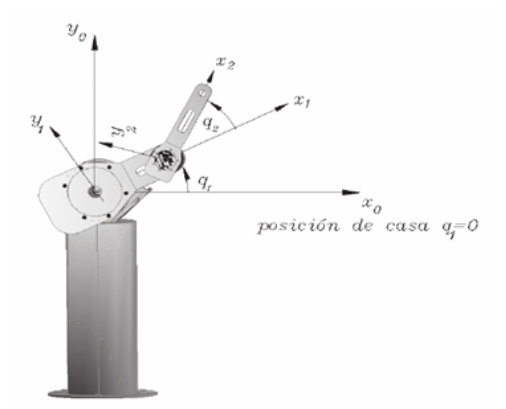

Para la posición de la articulación 1 respecto al origen del sistema de coordenadas. está se situa a lo largo del eje z del sistema de coordenadas global en l1 unidades. Y para su matriz de rotación colocamos una matriz de rotación en "y" de 90° convolucionada con la matriz de rotación en z con th1.

Para la articulación 2 su posición se define en relación con la articulación 1, y su posición en el plano xy depende de `l2` y de `th2`. Y para su matriz de rotación solo se coloca la matriz de rotación en "z".

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0;0;l1];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= [cos(th1) 0  -sin(th1);
           sin(th1) 0   cos(th1);
           0       -1         0];

%Articulación 2
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [l2*cos(th2); l2*sin(th2);0];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,2)= [cos(th2) -sin(th2)  0;
           sin(th2)  cos(th2)  0;
           0         0         1];

Continuamos con la creacion un vector de ceros de tamaño 1x3 que se utilizará más adelante en la construcción de matrices de transformación Homogénea locales y globales.

Dentro del bucle `for`, se itera sobre un rango que esta definido por la variable `GDL(en este caso es 2)`. Dentro de este bucle, se construye una matriz de transformación homogénea local utilizando las matrices de rotación y posicion, junto con el vector de ceros.c. Se intenta construir la matriz de transformación global multiplicando la matriz de transformación global del paso anterior por la matriz de transformación homogénea local actual . Si `i` es igual a 1, se utiliza solo la matriz de transformación homogénea local. Se extraen las matrices de rotación y posicion vistas desde el marco de referencia inercial a partir de la matriz de transformación global.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
%     disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
%     pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Continuamos con el calculo del Jacoviano de la velocidad angular y lineal, y comenzamos inicializando las matrices `Jv_a` y `Jw_a` para almacenar los componentes del Jacobiano lineal y angular respectivamente. 

Dentro del bucle `for` que itera sobre cada grado de libertad, se calculan los componentes del Jacobiano lineal y angular, se verifica si la articulación es de tipo angular o prismática, esto se hace revisando el valor en el vector `RP` en la posición `k`.

Para juntas angulares:

Se intenta calcular el Jacobiano lineal utilizando la fórmula del producto cruz entre el vector de rotación de la articulación anterior (`RO(:,3,k-1)`) y la diferencia entre las posiciones de las articulaciones (`PO(:,:,GDL) - PO(:,:,k-1)`).

Se calcula el Jacobiano angular directamente utilizando el vector de rotación de la articulación anterior (`RO(:,3,k-1)`).

Si hay un error en el cálculo, se asignan valores predeterminados para los componentes del Jacobiano lineal y angular.

Para juntas prismáticas:

Se calcula el Jacobiano lineal utilizando el vector de rotación de la articulación anterior (`RO(:,3,k-1)`), ya que las juntas prismáticas solo afectan el movimiento lineal.

Finalmente, se combinan las matrices `Jv_a` y `Jw_a` para formar la matriz de Jacobiano completa `Jacobiano`, que contiene tanto los componentes lineales como angulares del Jacobiano.

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac);
% pretty(Jacobiano);

Ahora con el Jacobiano podemos calcular la velocidad angular y lineal del sistema

%Obtenemos vectores de Velocidades Lineales y Angulares
% disp('Velocidad lineal obtenida mediante el Jacobiano lineal');
V=simplify (Jv_a*Qp);
% pretty(V);
% disp('Velocidad angular obtenida mediante el Jacobiano angular');
W=simplify (Jw_a*Qp);
%     pretty(W);

En la siguiente parte calcularemos la energía cinética, comenzando calculando la posición del centro de masa del eslabón respecto a su origen y se almacena en la variable `P01 y P02`. Esto se hace mediante la sustitución de la longitud del eslabón por su longitud al centro de masa. Posteriormente se define la matriz de inercia para cada eslabón, que contiene los momentos de inercia y los productos de inercia respecto a los ejes principales del eslabón.

Posteriormente extraemos las velocidades lineales y angulares del sistema, para calcular las velocidades del eslabón. Para el eslabón 1, se había calculado previamente al multiplicar la matriz Jacobiana por las velocidades de las articulaciones (`Qp`).

Eslabón 1:

Para el cálculo de las Velocidades para el Eslabón 1, primero se calcula el Jacobiano lineal y angular del eslabón 1 de manera analítica. Esto implica calcular las velocidades lineales y angulares del eslabón en función de las velocidades articulares (`Qp`) utilizando la relación entre las velocidades lineales y angulares de los eslabones y las velocidades articulares.Una vez que ya tenemos las matriz del Jacobiano completa, se obtienen los vectores de velocidades lineales y angulares del eslabón 1 utilizando el Jacobiano obtenido anteriormente.

Y terminamos calculando la energía cinética del eslabón 1. Esto implica calcular tanto la energía cinética translacional como la rotacional y sumarlas.

Eslabón 2:

No es necesario calcular el jacobiano lineal y angular, y las velocidades de este eslabon ya que se había calculado previamente al multiplicar la matriz jacobiana por `Qp`.

Y para el calculo de la energía cinética del eslabón 2. Calculamos tanto la energía cinética translacional como la rotacional y las sumamos.

Y por ultimo se suman las energías cinéticas de ambos eslabones para obtener la energía cinética total del sistema.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Energía Cinética
%%%%%%%%%%%%%%%%%%%%%%%%%%Omitimos la división de cada lc%%%%%%%%%%%%%%%
%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
 P01=subs(P(:,:,1), l1, lc1);
 P02=subs(P(:,:,2), l2, lc2);

%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

%Función de energía cinética

%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos las velocidades angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);

%Calculamos las velocidades para cada eslabón 

%Eslabón 1

%Calculamos el jacobiano lineal de forma analítica
Jv_a1(:,GDL-1)=PO(:,:,GDL-1);
Jw_a1(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
 %disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');
Qp=Qp(t);
V1=simplify (Jv_a1*Qp(1));
 %pretty(V1);
 % disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');
W1=simplify (Jw_a1*Qp(1));
 % pretty(W1);


%Eslabón 2
%Ya lo calculamos previamente al multiplicar la matriz jacobiana por Qp

%%%%%%%%%%%%%%%%%%%%%%%%
%Calculamos la energía cinética para cada eslabon

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
disp('Energía Cinética en el Eslabón 1');

Energía Cinética en el Eslabón 1


K1= simplify (K1);
pretty (K1);

              2
Izz1 |th1p(t)|
---------------
       2





%Eslabón 2
V2_Total= V+cross(W,P02);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W)'*(I2*W);
disp('Energía Cinética en el Eslabón 2');

Energía Cinética en el Eslabón 2


K2= simplify (K2);
pretty (K2);

                                                                                                                 /            2                2                2 \                                                                                                          /            2                2                2 \
          __                                                                                                     | #2 #3 |lc2|    #2 #6 #3 |l2|    #1 #5 #4 |l2|  |   __                                                                                                     | #2 #4 |lc2|    #2 #3 #5 |l2|    #1 #6 #4 |l2|  |
          m2 (lc2 cos(th2(t)) th1p(t) + l2 cos(th1(t)) cos(th2(t)) th1p(t) - l2 sin(th1(t)) sin(th2(t)) th2p(t)) | ------------ + -------------- - -------------- |   m2 (lc2 sin(th2(t)) th1p(t) + l2 cos(th2(t)) sin(th1(t)) th1p(t) + l2 cos(th1(t)) sin(th2(t)) th2p(t)) | ------------ + -------------- + -------------- |                                         


K_Total= simplify (K1+K2);
pretty (K_Total);

                                                                                                                           /            2                2                2 \                                                                                                          /            2                2                2 \
                    __                                                                                                     | #1 #3 |lc2|    #1 #6 #3 |l2|    #2 #5 #4 |l2|  |   __                                                                                                     | #1 #4 |lc2|    #1 #3 #5 |l2|    #2 #6 #4 |l2|  |
                    m2 (lc2 cos(th2(t)) th1p(t) + l2 cos(th1(t)) cos(th2(t)) th1p(t) - l2 sin(th1(t)) sin(th2(t)) th2p(t)) | ------------ + -------------- - -------------- |   m2 (lc2 sin(th2(t)) th1p(t) + l2 cos(th2(t)) sin(th1(t)) th1p(t) + l2 cos(th1(t)) sin(th2(t)) th2p(t)) | ------------ + -------------- + -------------- |           

Como siguiente paso calculamos la energía potencial, primero obteniendo la altura de nuestro segmento respecto a eje “y” y calculamos la energía potencial total multiplicando la masa por gravedad y altura.

%Calculamos la energía potencial para cada uno de los eslabones

%Obtenemos las alturas respecto a la gravedad
 h1= P01(2); %Tomo la altura paralela al eje y
 h2= P02(2); %Tomo la altura paralela al eje y

 %Calculamos la energía potencial total
 U1=m1*g*h1;
 U2=m2*g*h2;
 U_Total= U1 + U2;

Ahora que contamos con energía cinética y potencial podemos obtener el Largargiano y el modelo de energía, simplemente tenemos que restar la energía cinética de la energía potencial para el Lagargiano y en viceversa, debemos sumar ambas energías para el modelo de energía.

 %Obtenemos el Lagrangiano
 Lagrangiano= simplify (K_Total-U_Total);
 %pretty (Lagrangiano);

%Modelo de Energía
 H= simplify (K_Total+U_Total);
  %pretty (H)

Para el calculo de las ecuaciones de movimiento, primero se define un vector `Qd` que contiene las velocidades generalizadas del sistema, para despues calcular las derivadas temporales de la velocidad para la primera coordenada generalizada (`th1`). Esto implica calcular las segundas derivadas del Lagrangiano del sistema con respecto a la velocidad y la posición angular (`th1`) y con respecto a la velocidad y la velocidad angular (`th1p`), lo que proporciona las aceleraciones y las fuerzas de Coriolis y Centrífugas.

Y para el torque, utilizamos la expresión de la derivada temporal de la cantidad de movimiento generalizada menos el gradiente del Lagrangiano.

  %%%%%%%%%%%%%%%%%%%%%%Ecuaciones de Movimiento%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 Qd=[th1p(t); th2p(t); th1pp(t); th2pp(t)];

 %Obtenemos las derivadas de la velocidad en la primera coordenada
 %generalizada
 dQ1=[diff(diff(Lagrangiano,th1p), th1),diff(diff(Lagrangiano,th1p), th2),... %Derivamos con respecto a la primera velocidad generalizada th1p para las 2 posiciones articulaciones
     diff(diff(Lagrangiano,th1p), th1p),diff(diff(Lagrangiano,th1p), th2p)];%Derivamos con respecto a la primera velocidad generalizada th1p para las 2 velocidades articulaciones
 
 %Definimos el torque 1
 t1= dQ1*Qd- diff(Lagrangiano, th1);
 disp("Torque 1:");
 pretty (t1)

 %Obtenemos las de derivadas de la velocidad en la segunda coordenada
 %generalizada

 dQ2=[diff(diff(Lagrangiano,th2p), th1),diff(diff(Lagrangiano,th2p), th2),... %Derivamos con respecto a la segunda velocidad generalizada th2p para las 3 posiciones articulaciones
     diff(diff(Lagrangiano,th2p), th1p),diff(diff(Lagrangiano,th2p), th2p)];%Derivamos con respecto a la segunda velocidad generalizada th2p para las 3 velocidades articulaciones

 %Definimos el torque 2
 t2= dQ2*Qd- diff(Lagrangiano, th2);
 disp("Torque 2:");
 pretty(t2)

Por ultimo se calcula la matriz de inercia del sistema, que representa cómo la masa está distribuida y cómo resiste al cambio de velocidad. Esto se hace derivando el torque definido anteriormente con respecto a la aceleración generalizada para obtener los coeficientes de la matriz de inercia. Luego, se extraen los coeficientes correspondientes a las aceleraciones del sistema.

%Generación del Modelo Dinámico en forma matricial
%Matriz de Inercia
%Extraemos coeficientes de aceleraciones
M=[diff(t1, th1pp), diff(t1, th2pp);...
   diff(t2, th1pp), diff(t2, th2pp)];
rank (M);
M=M(t);
disp("Matriz de inercia:");
pretty(M)

Despues se calculan las fuerzas centrípetas y de Coriolis del sistema. Esto se hace derivando parcialmente el producto de la matriz de inercia por las velocidades generalizadas con respecto a las posiciones generalizadas y las velocidades generalizadas. Luego, se sustituyen las velocidades y aceleraciones en la derivada de la energía cinética con respecto a las posiciones para obtener las fuerzas centrípetas y de Coriolis.

 %Fuerzas Centrípetas y de Coriolis
 %Definimos Mp
 M11=[diff(M(1,1),th1), diff(M(1,1),th2)]*Qp;%Se deriva parcialmente en el tiempo respecto a todas las variables 
 M12=[diff(M(1,2),th1), diff(M(1,2),th2)]*Qp;

 M21=[diff(M(2,1),th1), diff(M(2,1),th2)]*Qp;
 M22=[diff(M(2,2),th1), diff(M(2,2),th2)]*Qp;

  Mp=[M11, M12;...
     M21, M22];

%Definimos la energía cinética en su forma matricial
k=1/2*transpose(Qp)*M*Qp;

%Definimos dk

dk=[diff(k, th1); diff(k, th2)];

%Fuerzas centrípetas y de Coriolis
 C= Mp*Qp-dk;
 disp("Modelo de las fuerzas centripetas y de Coriolis:");
 pretty(C)

Para el par gravitacional actuando sobre el sistema. Se sustituyen las velocidades y aceleraciones en la expresión del torque definido anteriormente. En este caso, se han sustituido las velocidades y aceleraciones por cero, por que se está calculando el par gravitacional en una posición específica del sistema.

Se define un vector G que contiene los pares gravitacionales para todas las articulaciones del sistema.


 %Par Gravitacional
 %se sustituyen las velocidades y aceleraciones por 0
 r=cero;
 a1=subs(t1, th1p, r);
 a2=subs(a1, th2p, r);
 a3=subs(a2, th1pp,r);
 a4=subs(a3, th2pp,r);

 %Torque gravitacional en el motor 1
 G1=a4;

 
 b1=subs(t2, th1p, r);
 b2=subs(b1, th2p, r);
 b3=subs(b2, th1pp,r);
 b4=subs(b3, th2pp,r);

 %Torque gravitacional en el motor 2
 G2=b4;


% Vector de par gravitsacional

G=[G1;G2];
disp("Vector de par gravitacional:");
pretty(G)

 toc

Elapsed time is 7.886000 seconds.
